# Chapter 2, Section 1 (Part 1)

The goal of this activity is an introduction to vectors in $R^n$. Let's first look at $R^2$.


$$R^2=\left\{\pmatrix{x_1\cr x_2}:\ x_1, x_2\in R\right\}$$


Note that each vector in $R^2$ is a column vector with two real entries.

# Example #1

Sketch the vector $\vec u=\pmatrix{2\cr 2}$ and calculate its length.

**Solution: **We can use an arrow, starting at the origin and ending at the point (2,2) to represent this vector.

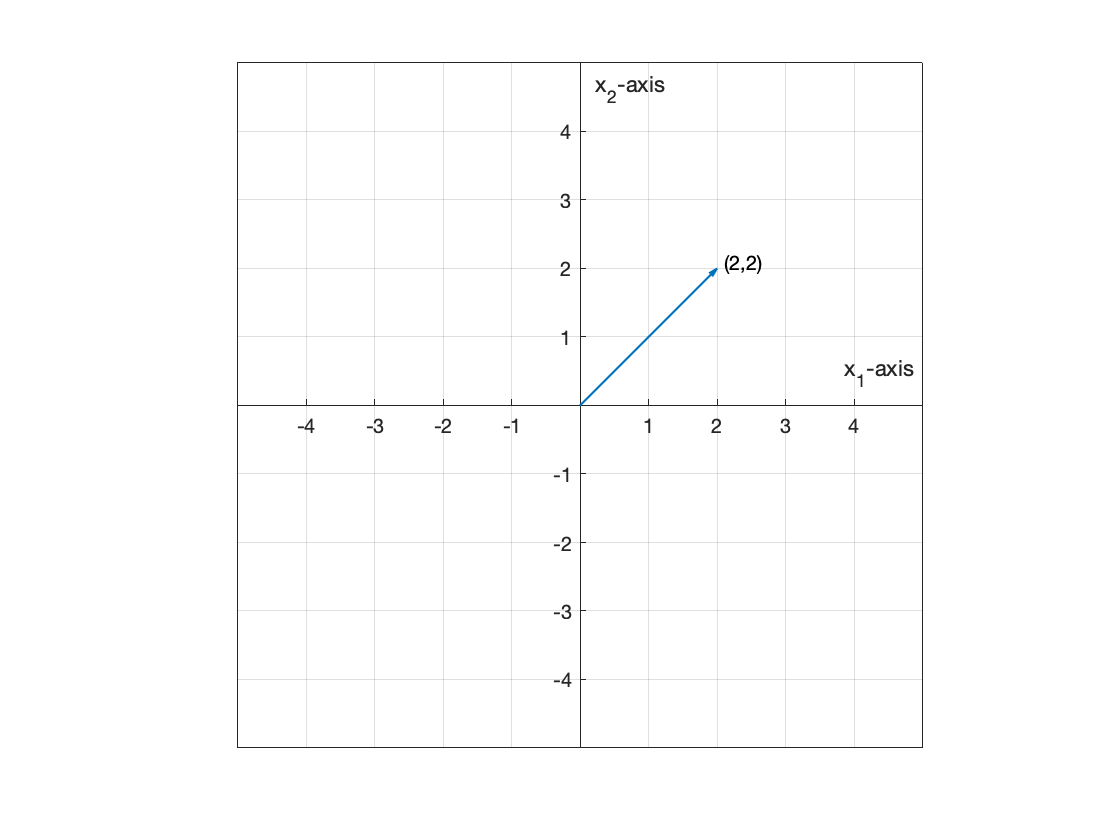

quiver(0,0,2,2,0,'linewidth',1)
axis equal
axis([-5,5,-5,5])
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
xlabel('x_1-axis')
ylabel('x_2-axis')
text(2.1,2.1,'(2,2)')

We can use the Pythagorean Theorem to compute the length of the vector. 

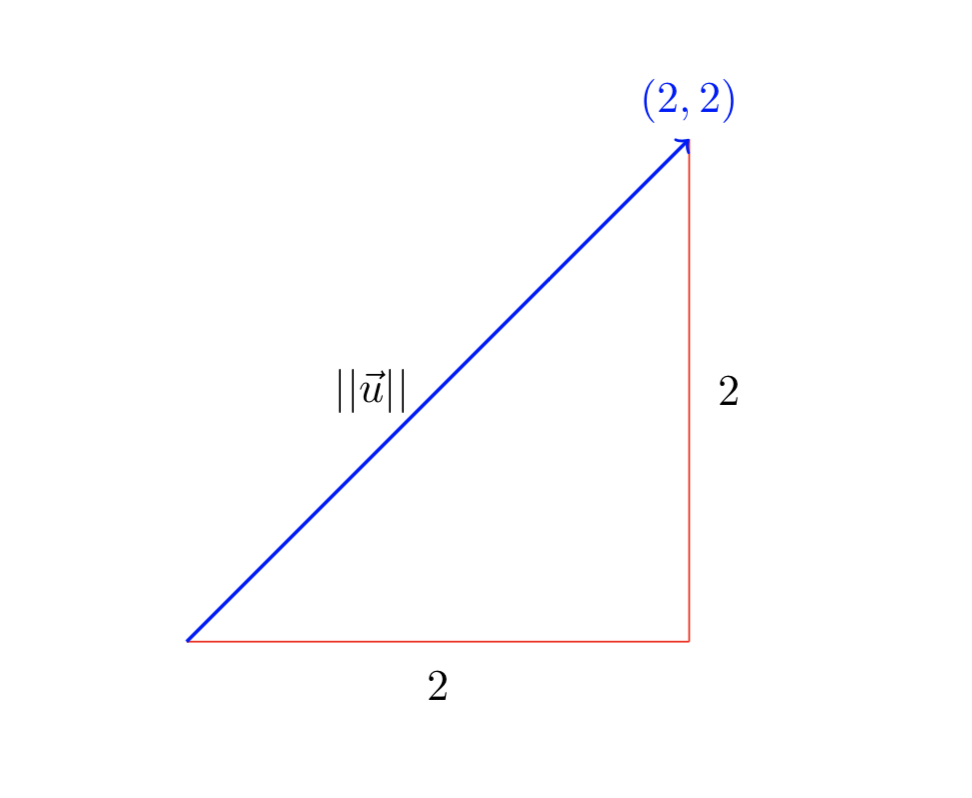

The notation $||\vec u||$ means the **norm** (or length) of the vector $||\vec u||$.


$$\begin{array}{rcl}
||\vec u||&=&\sqrt{2^2+2^2}\\
||\vec u||&=&\sqrt{8}\\
 ||\vec u||&=&2\sqrt{2}\\
\end{array}$$


Let's check this with the Symbolic Toolbox.

u=[2;2];
norm(sym(u))

$$ans = \sqrt{8}$$

Let's get a decimal approximation.

norm(u)

ans = 2.8284

In our image above, does this seem reasonable? Let's add a circle of radius 2.8284 to our image.

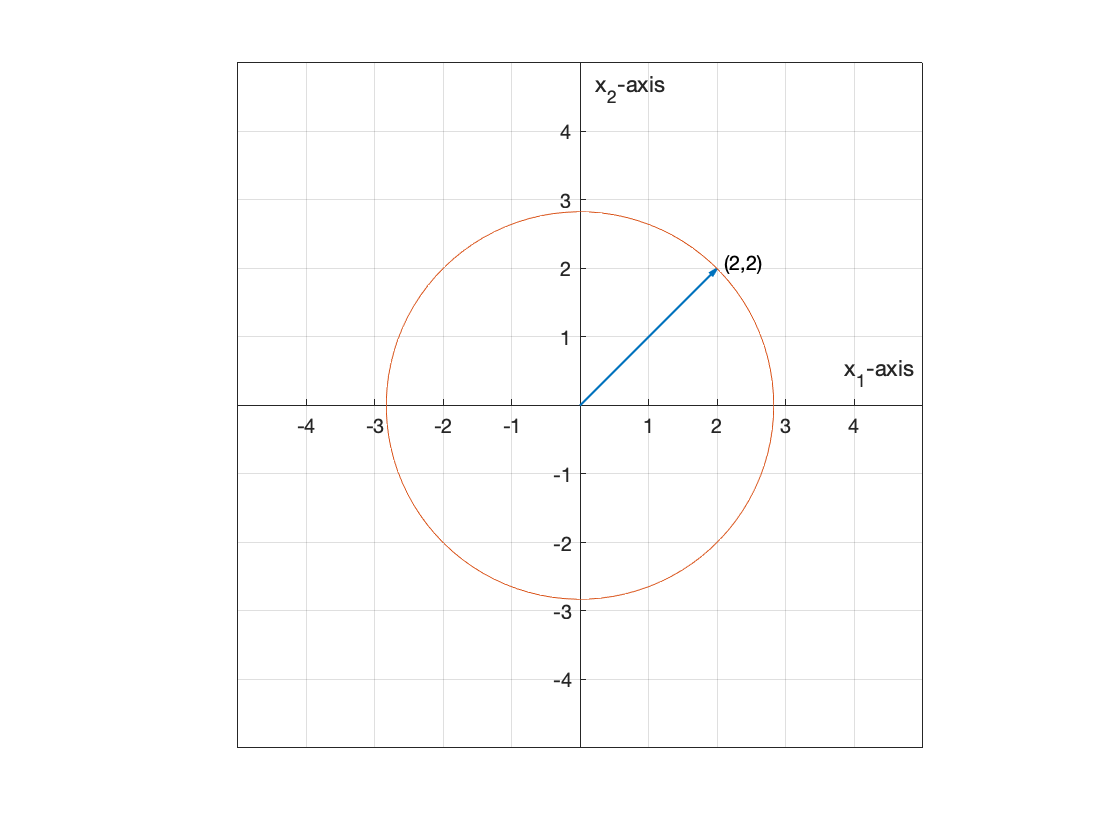

quiver(0,0,2,2,0,'linewidth',1)
hold on
t=linspace(0,2*pi);
r=2.8284;
x=r*cos(t);
y=r*sin(t);
plot(x,y)
axis equal
axis([-5,5,-5,5])
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
xlabel('x_1-axis')
ylabel('x_2-axis')
text(2.1,2.1,'(2,2)')
hold off

Yes, that length is quite reasonable. Note that the circle intersects the $x_1$ axis at about 2.8. 

# Vector Addition

Now, think of a rope tied around our waste and someone is pulling on the rope with $2\sqrt2$ pounds of force in the direction of the vector in Example #1. Now, suppose a second rope is tied around our waist and another person is pulling toward the point $(-2,2)$ with the same $2\sqrt2$ pounds of force. Let's add this vector to our image.

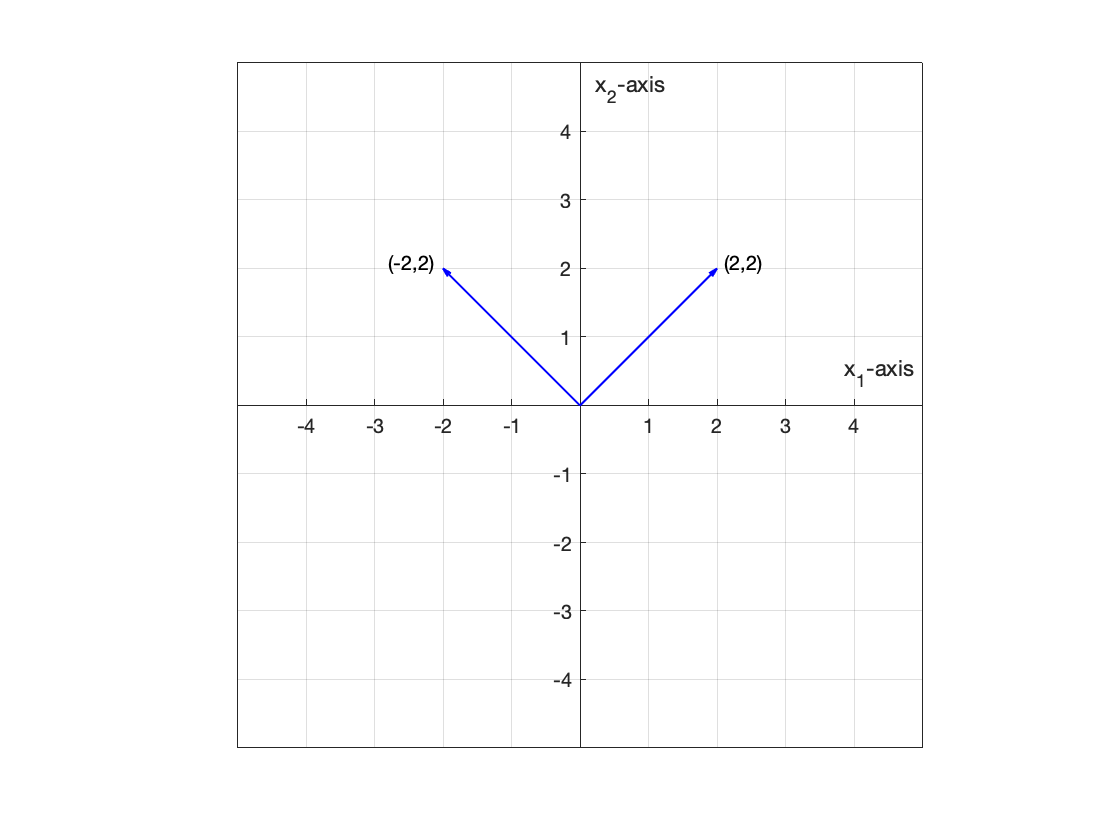

quiver(0,0,2,2,0,'LineWidth',1,'Color','b'),hold on
quiver(0,0,-2,2,0,'LineWidth',1,'Color','b')
axis equal
grid on 
axis([-5,5,-5,5])
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
xlabel('x_1-axis')
ylabel('x_2-axis')
text(2.1,2.1,'(2,2)')
text(-2.8,2.1,'(-2,2)')
hold off

It makes sense that the combined forces that we are feeling will force us (providing we are not replying with any resistance) to move in the direction of the $x_2$-axis and the force will be much more than $2\sqrt2$ pounds. Indeed, here is how we combine (add) these two vectors.

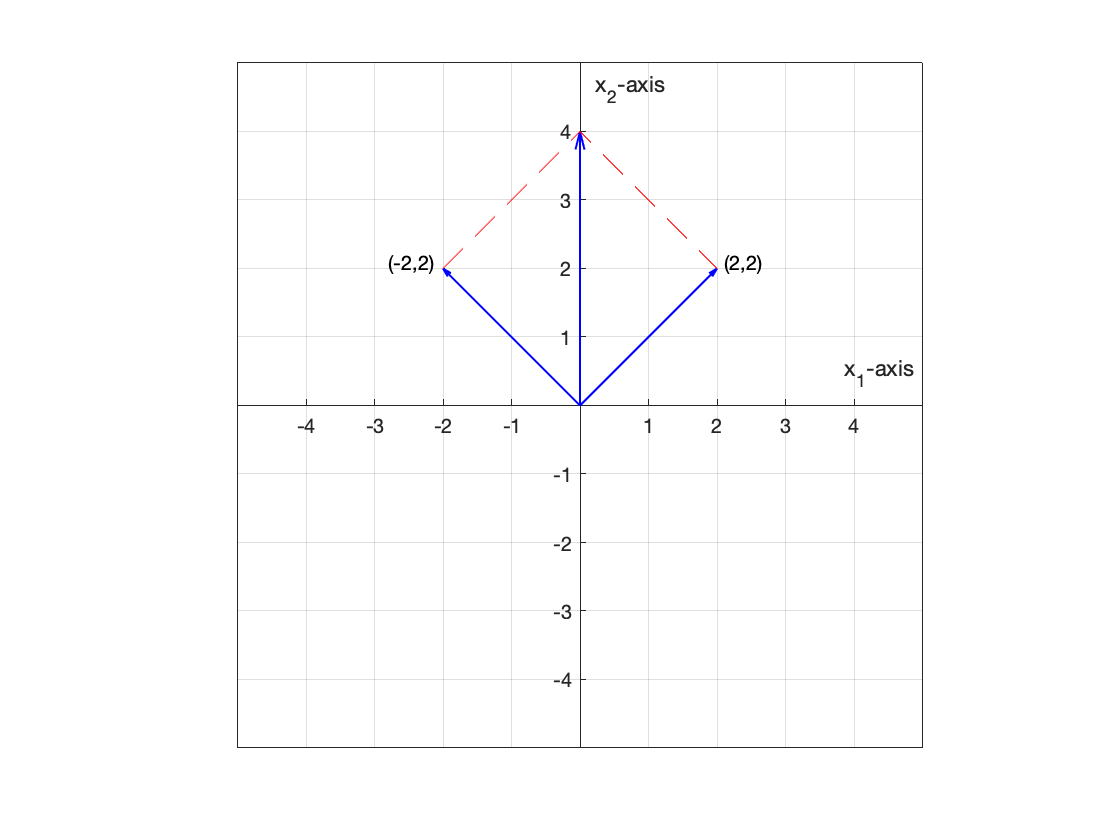

quiver(0,0,2,2,0,'LineWidth',1,'Color','b'),hold on
quiver(0,0,-2,2,0,'LineWidth',1,'Color','b')
quiver(0,0,0,4,0,'LineWidth',1,'Color','b')
line([-2,0,2],[2,4,2],'LineStyle','--','Color','r')
axis equal
grid on 
axis([-5,5,-5,5])
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
xlabel('x_1-axis')
ylabel('x_2-axis')
text(2.1,2.1,'(2,2)')
text(-2.8,2.1,'(-2,2)')
hold off

This technique is called the "parallelogram method" for adding vectors. Now, our answer appears to be the vector $\pmatrix{0\cr 4}$. Let's add our two vectors together by simply adding their corresponding elements.


$$\begin{array}{rcl}
\vec u+\vec v&=&\pmatrix{2\cr 2}+\pmatrix{-2\cr 2}\\
\vec u+\vec v&=&\pmatrix{0\cr 4}
\end{array}$$


How about Matlab?

u=[2;2];
v=[-2;2];
u+v

ans =      0
     4


Same answer. This gives us the same answer as our geometric parallelogram method. So, in general, here is how we add two vectors in $R^2$.


$$\begin{array}{rcl}
\vec u+\vec v&=&\pmatrix{u_1\cr u_2}+\pmatrix{v_1\cr v_2}\\
\vec u+\vec v&=&\pmatrix{u_1+v_1 \cr u_2+v_2}
\end{array}$$


# Scalar Multiplication

Suppose someone is tugging us with a certain amount of force in a particular direction. What do we suppose would happen if they decided to double the force in the same direction? Let's visualize 2 times the vector $\pmatrix{2\cr 2}$.

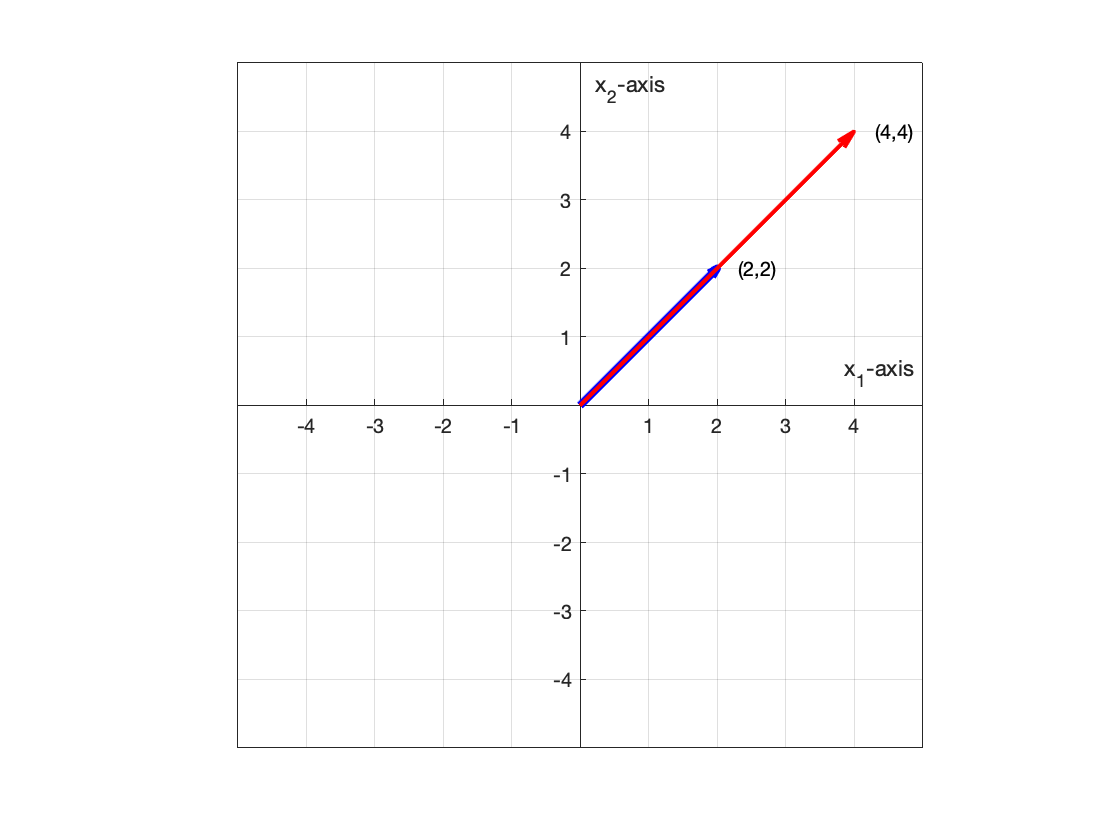

quiver(0,0,2,2,0,'linewidth',4,'Color','b')
hold on
quiver(0,0,4,4,0,'linewidth',2,'Color','r')
axis equal
axis([-5,5,-5,5])
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
xlabel('x_1-axis')
ylabel('x_2-axis')
text(2.3,2,'(2,2)')
text(4.3,4,'(4,4)')
hold off

Sure enough, we get a vector that is twice as long pointing in the same direction. Let's calculate its length to verify this statement.


$$\begin{array}{rcl}
||\vec v||&=&\sqrt{4^2+4^2}\\
||\vec v||&=&\sqrt{32}\\
||\vec v||&=&4\sqrt{2}\\
\end{array}$$


Perfect. Vector $\vec u$ above had a length of $||\vec u||=2\sqrt2$ and our new vector $\vec v$ has a length $||\vec v||=4\sqrt2$, so it is exactly twice as long. Additionally, our answer gives us evidence that they way to multiply a scalar times a vector is to simply multiply the scalar times each component of the vector.


$$\begin{array}{rcl}
\vec v&=&2\vec u\\
\vec v&=&2\pmatrix{2\cr 2}\\
\vec v&=&\pmatrix{4\cr 4}\\
\end{array}$$


Which agrees with our visualization above. How about Matlab?

u=[2;2];
v=2*u

v =      4
     4


Same answer. Therefore, in general, here is how we multiply a scalar times a vector.


$$\begin{array}{rcl}
c\vec u&=&c\pmatrix{u_1\cr u_2}\\
c\vec u&=&\pmatrix{c u_1\cr c u_2}\\
\end{array}$$


What happens when we multiply by a negative scalar?

# Example #2

If $\vec u=\pmatrix{4\cr 4}$, sketch $\vec u$ and $-\frac12\vec u$.

**Solution:** We imagine that $-\frac12\vec v$ will be half as long but point in the opposite direction. 

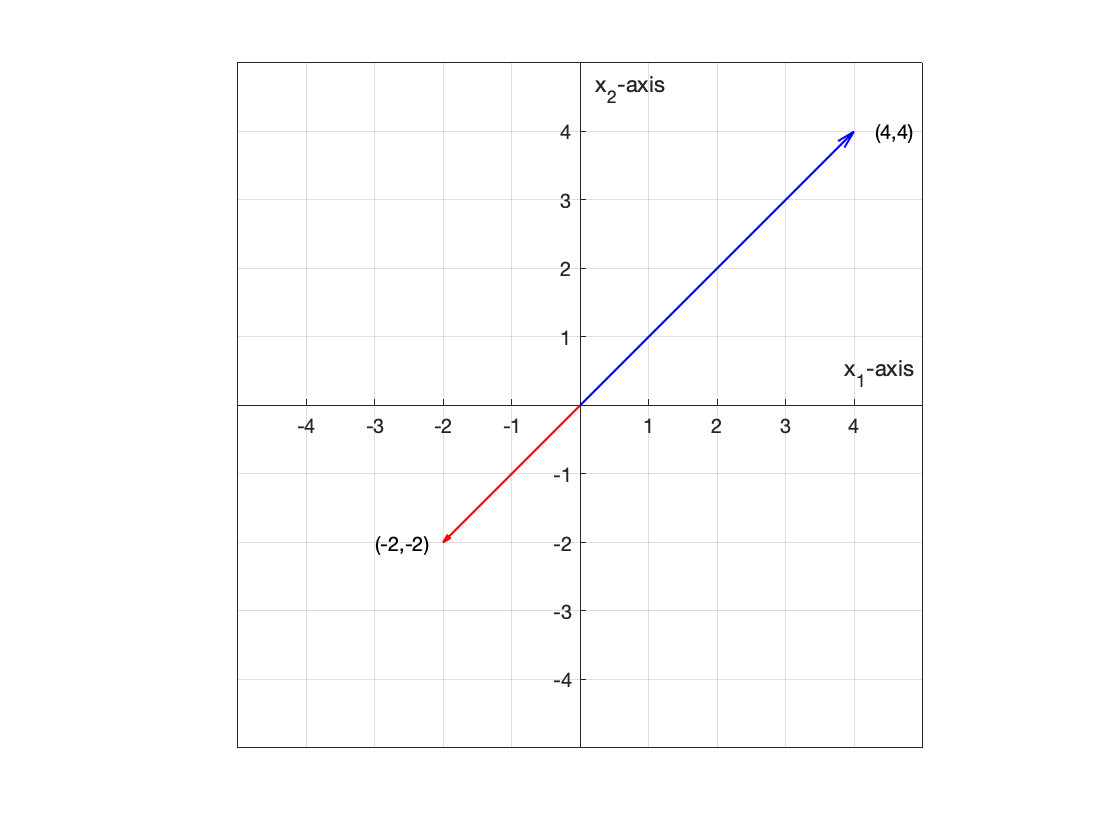

quiver(0,0,4,4,0,'linewidth',1,'Color','b')
hold on
quiver(0,0,-2,-2,0,'linewidth',1,'Color','r')
axis equal
axis([-5,5,-5,5])
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
xlabel('x_1-axis')
ylabel('x_2-axis')
text(4.3,4,'(4,4)')
text(-3,-2,'(-2,-2)')
hold off

Sure enough. And this image gives us good evidence that


$$\begin{array}{rcl}
-\frac12\vec u&=&-\frac12\pmatrix{4\cr 4}\\
-\frac12\vec u&=&\pmatrix{-2\cr -2}\\
\end{array}$$


How about Matlab?

u=[4;4];
-1/2*u

ans =     -2
    -2


Same answer.

# Vector Subtraction

The difference of two vectors is defined as:


$$\vec u-\vec v=\vec u+(-\vec v)$$


Let's visualize an example.

# Example #3

Let $\vec u=\pmatrix{3\cr 1}$ and $\vec v=\pmatrix{1\cr 2}$. Sketch $\vec u-\vec v$.

**Solution: ** $\vec u-\vec v$ is defined as $\vec u+(-\vec v)$ above. We know that $-\vec v=-1\vec v$ will be a vector of the same length as $\vec v$, but pointing in the opposite direction. So, here is what we will do:

- Sketch $\vec u$ and $\vec v$.

- Sketch $-\vec v$ as a vector of the same length, but pointing in the opposite direction.,

- Use the parallelogram method to add $\vec u+(-\vec v)$.

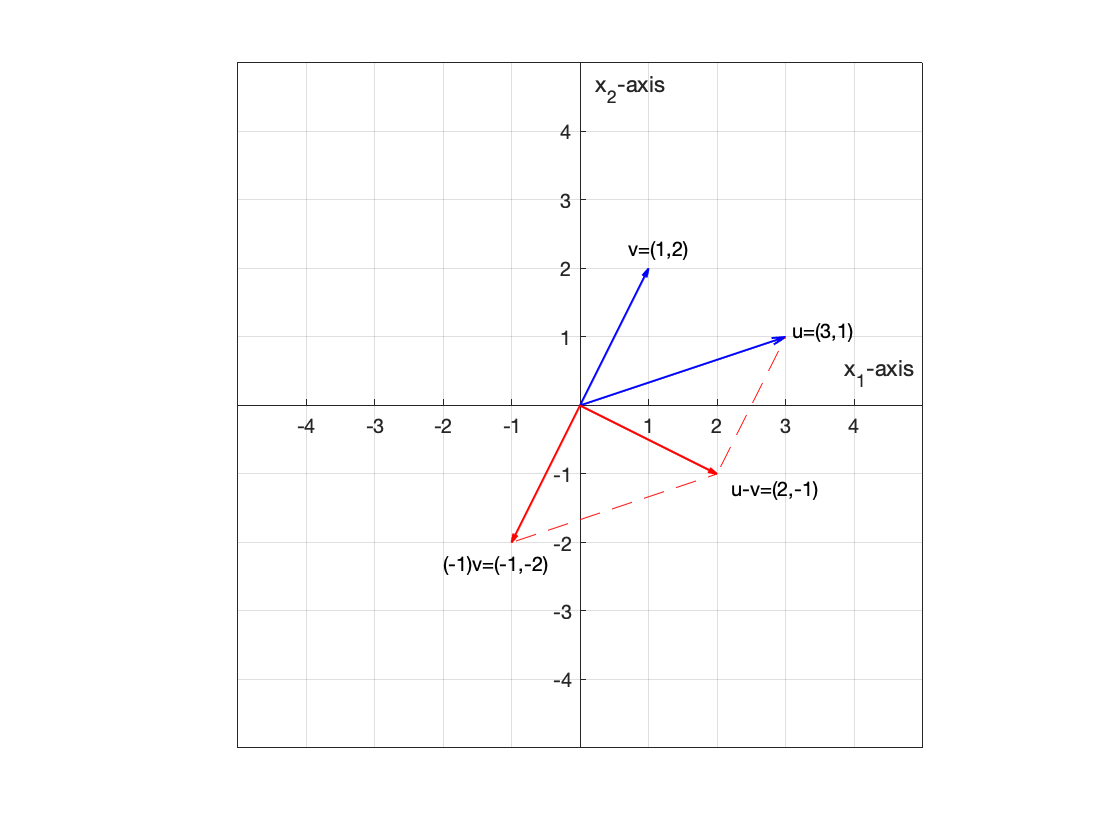

quiver(0,0,3,1,0,'linewidth',1,'Color','b')
hold on
quiver(0,0,1,2,0,'linewidth',1,'Color','b')
quiver(0,0,-1,-2,0,'linewidth',1,'Color','r')
quiver(0,0,2,-1,0,'linewidth',1,'Color','r')
line([3,2],[1,-1],'LineStyle','--','Color','r')
line([-1,2],[-2,-1],'LineStyle','--','Color','r')
axis equal
axis([-5,5,-5,5])
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
xlabel('x_1-axis')
ylabel('x_2-axis')
text(3.1,1.1,'u=(3,1)')
text(0.7,2.3,'v=(1,2)')
text(-2,-2.3,'(-1)v=(-1,-2)')
text(2.2,-1.2,'u-v=(2,-1)')
hold off

Therefore, we could subtract the two vectors as follows:


$$\begin{array}{rcl}
\vec u-\vec v&=&\vec u+(-1)\vec v\\
\vec u-\vec v&=&\pmatrix{3\cr 1}+(-1)\pmatrix{1\cr 2}\\
\vec u-\vec v&=&\pmatrix{3\cr 1}+\pmatrix{-1\cr -2}\\
\vec u-\vec v&=&\pmatrix{2\cr -1}
\end{array}$$


Matlab check.

u=[3;1];
v=[1;2];
u-v

ans =      2
    -1


Same answer, which agrees with our image above. However, a little geometry reveals a much faster way.

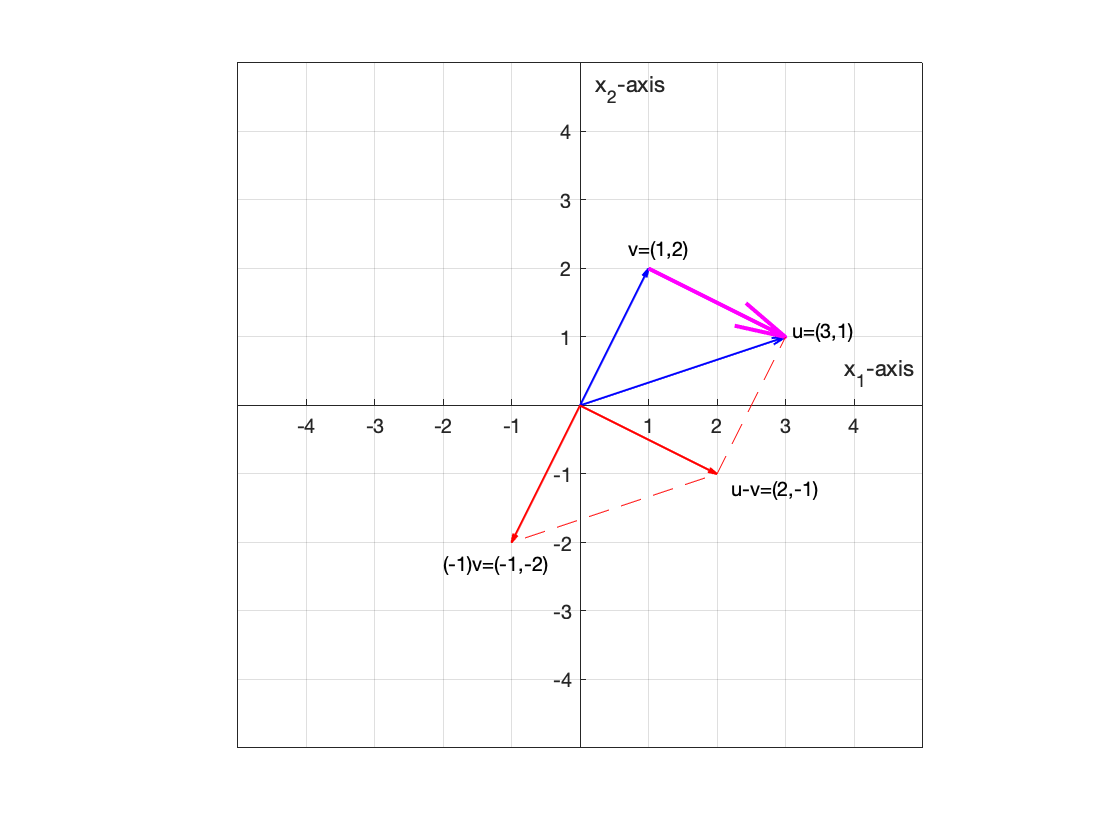

quiver(0,0,3,1,0,'linewidth',1,'Color','b')
hold on
quiver(0,0,1,2,0,'linewidth',1,'Color','b')
quiver(0,0,-1,-2,0,'linewidth',1,'Color','r')
quiver(0,0,2,-1,0,'linewidth',1,'Color','r')
quiver(1,2,2,-1,0,'linewidth',2,'Color','m','MaxHeadSize',5)
line([3,2],[1,-1],'LineStyle','--','Color','r')
line([-1,2],[-2,-1],'LineStyle','--','Color','r')
axis equal
axis([-5,5,-5,5])
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
xlabel('x_1-axis')
ylabel('x_2-axis')
text(3.1,1.1,'u=(3,1)')
text(0.7,2.3,'v=(1,2)')
text(-2,-2.3,'(-1)v=(-1,-2)')
text(2.2,-1.2,'u-v=(2,-1)')
hold off

We've add another vector our image that starts at the point $(1,2)$ and points and arrives at the point $(3,1)$. Note that it points in the same direction as the vector $\vec u-\vec v$ and is the same length as the vector $\vec u-\vec v$. Therefore, it is equal to the vector $\vec u-\vec v$. This gives us a really easy way to sketch the vector $\vec u-\vec v$; start at the tip of vector $\vec v$, then travel to the tip of vector $\vec u$. Also, note that if we start at the point $(1,2)$, then move 2 to the right and 1 unit down, we arrive at the point $(3,1)$. This also gives us good evidence that $\vec u-\vec v=\pmatrix{2\cr -1}$; i.e., 2 units to the right, 1 unit down.

Thus, a much easier way to subtract two vectors is simply to subtract their corresponding coordinates.


$$\begin{array}{rcl}
\vec u-\vec v&=&\pmatrix{3\cr 1}-\pmatrix{1\cr 2}\\
\vec u-\vec v&=&\pmatrix{3-1\cr 1-2}\\
\vec u-\vec v&=&\pmatrix{2\cr -1}
\end{array}$$


So our final definition is:


$$\begin{array}{rcl}
\vec u-\vec v&=&\pmatrix{u_1\cr u_2}-\pmatrix{v_1\cr v_2}\\
\vec u-\vec v&=&\pmatrix{u_1-v_1\cr u_2-v_2}
\end{array}$$


# Example #4

Given $u=\pmatrix{1\cr 3}$ and $\vec v=\pmatrix{-4\cr 5}$, calculate $3(\vec u+\vec v)$ and $3\vec u+3\vec v$. Do we get the same answer?

**Solution:** This reminds us of the distributive property in algebra. Let's calculate $3(\vec u+\vec v)$.


$$\begin{array}{rcl}
3(\vec u+\vec v)&=&3\left(\pmatrix{1\cr 3}+\pmatrix{-4\cr 5}\right)\\
&=&3\pmatrix{1+(-4)\cr3+5}\\
&=&3\pmatrix{-3\cr8}\\
&=&\pmatrix{3(-3)\cr3(8)}\\
&=&\pmatrix{-9\cr24}\\
\end{array}$$


Let's check with Matlab.

u=[1;3];
v=[-4;5];
3*(u+v)

ans =     -9
    24


Same answer. Now, let's calculate $3\vec u+3\vec v$.


$$\begin{array}{rcl}
3\vec u+3\vec v&=&3\pmatrix{1\cr 3}+3\pmatrix{-4\cr 5}\\
&=&\pmatrix{3\cr 9}+\pmatrix{-12\cr 15}\\
&=&3\pmatrix{-9\cr 24}
\end{array}$$


Matlab check.

3*u+3*v

ans =     -9
    24


Same answer. This gives us strong evidence that $c(\vec u+\vec v)=c\vec u+c\vec v$.